clear all;
close all;
% 数字滤波器指标:
wp = 0.2*pi; % 数字通带频率(Hz)
ws = 0.5*pi; % 数字阻带频率(Hz)
Rp = 3; % 通带波动(dB)
Rs = 30; % 阻带波动(dB)
OmegaP=tan(wp/2); % 给出原始要求
OmegaS=tan(ws/2); % 给出原始要求
N0 = log10((10.^(0.1*abs(Rp))-1)./(10.^(0.1*abs(Rs))-1))/(2*log10(OmegaP/OmegaS));
N = ceil( N0 ) % 估算 N 的设计公式

N = 4

OmegaC = OmegaP / ( (10^(.1*abs(Rp)) - 1)^(1/(2*N)) ) % 估算 OmegaC 的设计公式

OmegaC = 0.3251

OmegaC = OmegaS / ( (10^(.1*abs(Rs)) - 1)^(1/(2*N)) ) % 估算 OmegaC 的设计公式

OmegaC = 0.4217

[N, OmegaC] =buttord(OmegaP, OmegaS, Rp, Rs, 's') % 调用信号处理工具箱中估算 N 和 OmegaC 的公式

N = 4

OmegaC = 0.4217

[z0,p0,k0] = buttap(N) % 调用 buttap 函数,得到系统的左半平面零极点


z0 =

     []



p0 =   -0.3827 + 0.9239i
  -0.3827 - 0.9239i
  -0.9239 + 0.3827i
  -0.9239 - 0.3827i


k0 = 1

b0=k0*real(poly(z0)), a0=real(poly(p0)) % 求归一化滤波器系数 b0,a0

b0 = 1

a0 =     1.0000    2.6131    3.4142    2.6131    1.0000


Nm=length(a0)-length(b0); % 求极点个数与零点个数之差 Nm
k = k0*OmegaC^Nm; % 将 k0 乘以 Omegac^Nm,得到非归一化 k
p = p0*OmegaC; z = z0*OmegaC; % 将零极点乘以 Omegac，得到非归一化零极点
b=k*real(poly(z)); a=real(poly(p)) % 求非归一化滤波器系数 b,a

a =     1.0000    1.1021    0.6073    0.1960    0.0316


%pause
wx=[OmegaP,OmegaS]/OmegaC; % 设置频率向量[OmegaP,OmegaS]
Hx=freqs(b0,a0,wx) % 计算该两点上的幅特性

Hx =   -0.5997 - 0.7280i   0.0134 + 0.0286i


dbHx=20*log10(abs(Hx)) % 化为分贝值，检验是否达到要求

dbHx =    -0.5081  -30.0000


freqs(b,a) % 画出波特图
[G,sos]=tf2sos(b0,a0) % 化为二阶级联形式

G =     1.0000         0         0    1.0000    1.8478    1.0000
    1.0000         0         0    1.0000    0.7654    1.0000


sos = 1

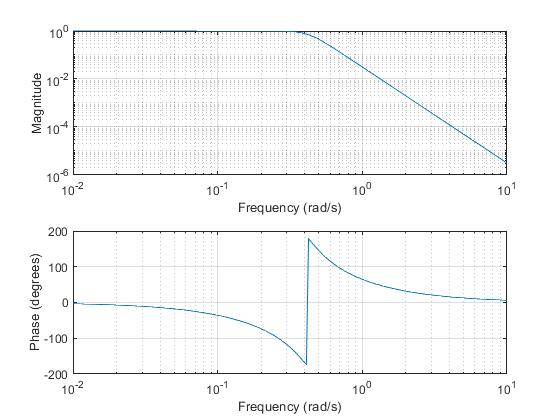

set(gcf,'color','w') % 置图形背景色为白